clear; close all; clc;

% Video file directory
% fileName = '/Users/andrewsias_m3p/Desktop/2DBM_March/2DBM_40Deg_SIGNAL_32to72-03032025183542-0000.avi';
fileName = "/Users/andrewsias_m3p/Desktop/2DBM_March/BPTPUA_CamOnly_40Deg-03112025084938-0000.avi";

% Make video object
vidObj = VideoReader(fileName);

% Define video processing length and frame skip interval
% startFrame = 400;
% endFrame   = 700;
% Whole video
startFrame = 1;
endFrame   = vidObj.NumFrames;

skipFrames = 4; % skipFrames = 2 will read every other frame, etc.

% Create array of frames you actually want to read
framesToRead = startFrame : skipFrames : endFrame;

% Read specified frames and convert to grayscale array
Process_Frames = readAndConvertVideo(vidObj, framesToRead);

% Crop video
sz = 1000; % size dimension (square)
xNudge = +160;
yNudge = -0;
Process_Frames = cropVideo(vidObj, Process_Frames, sz, xNudge, yNudge);
[process_height, process_width, process_length] = size(Process_Frames);

% Pseudo power meter readout
PowerMeter = powerMeterReadout(framesToRead, Process_Frames);

% Frames to stage angle detuning - FIX WITH ANGLE DATA!!
[~, BraggPeakIdx] = max(PowerMeter) % Power meter peak idx
BraggPeakFrame = framesToRead(BraggPeakIdx + 0) % real frame
angleRange = (framesToRead - BraggPeakFrame + 0) .* 0.022;
% Remove zero offset
PowerMeter = PowerMeter - min(PowerMeter);
% Scale to DE
PowerMeter = (PowerMeter ./ max(PowerMeter)) .* 0.7;

clear BraggPeakFrame;

% Plot "Power Meter" readout
figure
plot(angleRange,PowerMeter,'r-o'); hold on;
xline(0); hold off;

% % TEMP
% BraggPeakIdx = 65;

test_image = Process_Frames(:,:,BraggPeakIdx);
figure;
imshow(test_image);

% For image registration
first_Frame = Process_Frames(:,:,1);
last_Frame = Process_Frames(:,:,end);
% 
% figure; imshow(first_Frame);
% figure; imshow(last_Frame);

figure;
imshowpair(first_Frame,last_Frame,'montage');

%Image Registration

% load('ReferenceImage_0303.mat');
% load('testImage_0303.mat');
% MOVING = first_Frame;
FIXED  = test_image;

% movingReg01 = registerImages(MOVING,FIXED);
% Register_Frames(:,:,1) = movingReg01.RegisteredImage;
% Register_Displacement(:,:,:,1) = movingReg01.DisplacementField;

figure;
for idx = 1:process_length
movingReg01 = registerImages(Process_Frames(:,:,idx),FIXED);
Register_Frames(:,:,idx) = movingReg01.RegisteredImage;
imshow(Register_Frames(:,:,idx));
drawnow;

end
beep

function [MOVINGREG] = registerImages(MOVING,FIXED)
%registerImages  Register grayscale images using auto-generated code from Registration Estimator app.
%  [MOVINGREG] = registerImages(MOVING,FIXED) Register grayscale images
%  MOVING and FIXED using auto-generated code from the Registration
%  Estimator app. The values for all registration parameters were set
%  interactively in the app and result in the registered image stored in the
%  structure array MOVINGREG.

% Auto-generated by registrationEstimator app on 03-Mar-2025
%-----------------------------------------------------------


% Nonrigid registration
[MOVINGREG.DisplacementField,MOVINGREG.RegisteredImage] = imregdemons(MOVING,FIXED,100,'AccumulatedFieldSmoothing',1.0,'PyramidLevels',3);

end

% Section images into subarrays
blockSize = 10;
frameNum = BraggPeakIdx;
% imageCells = subDivideImage(Process_Frames, frameNum, blockSize);
load('register_Frames_Signal02.mat');
% Make stack of subdivided images
for idx = 1:process_length
    imageBlock{:,:,idx} = subDivideImage(Register_Frames, idx, blockSize);
end

% Check images
single_sheet = imageBlock{1,1,frameNum};
cellMat = cell2mat(single_sheet);
figure;
imagesc(cellMat);

% Average subarrays at every image
avgBlock = regionSums(imageBlock);

% Check Images
avgCellMat = avgBlock(:,:,frameNum);
figure;
imagesc(avgCellMat);

% % Isolate pixel data
% fitRegions = {}; % Cell array to downsize dimensions
% for x_px = 1:process_height
%     for y_px = 1:process_width
%         fitRegions{x_px,y_px} = squeeze(Process_Frames(x_px,y_px,:));
%     end
% end
% 
% % Remove Offset and Scale to DE
% for x_px = 1:process_height
%     for y_px = 1:process_width
%         fitRegions{x_px,y_px} = (fitRegions{x_px,y_px} - min(fitRegions{x_px,y_px}));
%         fitRegions{x_px,y_px} = double(fitRegions{x_px,y_px});
%         fitRegions{x_px,y_px} = (fitRegions{x_px,y_px} ./ max(fitRegions{x_px,y_px}) .* 0.96);
%     end
% end
% 
% % figure;
% % testTrace = fitRegions{100,100};
% % plot(angleRange, testTrace)

% % Plot line traces in x and y
% imageNum = 140;
% unfiltered_image = Process_Frames(:,:,imageNum);
% lineNum  = 300;
% x_trace = unfiltered_image(lineNum,:);
% y_trace = unfiltered_image(:,lineNum);
% 
% filtered_image = wiener2(unfiltered_image,[9,9],1);
% 
% x_trace_filt = filtered_image(lineNum,:);
% y_trace_filt = filtered_image(:,lineNum);
% 
% figure
% % imshowpair(unfiltered_image,filtered_image,'montage');
% imshow(unfiltered_image)
% xline(lineNum,'r'); yline(lineNum,'r');
% 
% figure
% plot(x_trace,'g'); hold on; plot(x_trace_filt,'b'); hold off;
% 
% figure
% plot(y_trace,'g'); hold on; plot(y_trace_filt,'b'); hold off;
% 
% transformed_image = fft2(unfiltered_image);
% 
% F = fftshift(transformed_image); % Center FFT
% 
% F = abs(F); % Get the magnitude
% F = log(F+1); % Use log, for perceptual scaling, and +1 since log(0) is undefined
% F = mat2gray(F); % Use mat2gray to scale the image between 0 and 1
% figure
% imshow(F,[]); % Display the result

% Fit "power meter" to CWT - USE MATERIAL ANGLE:
plot_title = char('Pseudo Power Meter Readout');
[OUT.CWT.in , OUT.CWT.out] = FitBraggSelectivity(angleRange,PowerMeter, ...
    'PlotKSpace', false,'PlotPhi', false,'PlotA', false, ...
    'RefWrtTheta', -19,'ObjWrtTheta', 19, ...
    'nWrt',1.5,'nRed', 1.5, 'lambdaWrt0', 405E-09, 'lambdaRed0', 635E-09, ...
    'L0', 0.00002,'n10', 0.005, ...
    'Born'   , false, ...
    'PlotTitle', plot_title);
axis([-15 15 0 0.6]);

% Save figure for re-plotting
saveas(gcf,convertCharsToStrings(plot_title));

% Re-plot power meter readout
clear; close all; clc;
openfig('Pseudo Power Meter Readout.fig');
left = 1;
bottom = 1;
width = 5.75;
height = 4.5;

set(gcf,'Units','inches','Position',[left bottom width height],'FontSize',16);

% % Peep at subregions
% figure;
% boxNum = 5;
% DE_trace = squeeze(avgBlock(boxNum,boxNum,:));
% DE_trace = DE_trace - min(DE_trace);
% DE_trace = (DE_trace ./ max(DE_trace) .*0.6);
% plot(angleRange,DE_trace);

globeMax = max(max(max(avgBlock)));

% figure;
for x_idx = 1:size(avgBlock,1)
    for y_idx = 1:size(avgBlock,2)
        DE_Trace = squeeze(avgBlock(x_idx,y_idx,:));
        DE_Trace = DE_Trace - min(DE_Trace);
        DE_Trace = (DE_Trace ./ globeMax) .* 0.7;
        DE_Trace(isnan(DE_Trace)) = 0;
        DE_Block{x_idx,y_idx} = DE_Trace;

        % plot(angleRange,DE_Block{x_idx,y_idx});
        % axis([-15 15 0 0.6]);
        % drawnow;
        % pause(1/30);
    end
end
% Cool 3D plot here?
% plot(angleRange,DE_Block);

% Fit video to CWT
% Fit "power meter" to CWT - USE MATERIAL ANGLE:
plot_title = char('Subregion Readout');

plotFitL = zeros(size(DE_Block,1),size(DE_Block,2));
plotFitn1 = zeros(size(DE_Block,1),size(DE_Block,2));
plotFitGof = zeros(size(DE_Block,1),size(DE_Block,2));

poolObj = parpool(12);
for x_px = 1:size(DE_Block,1)
    fprintf('Working on column %i\n',x_px)
    parfor y_px = 1:size(DE_Block,2)
        [~ , ~ , n1, L, GoF] = FitBraggSelectivity(angleRange,DE_Block{x_px,y_px}', ...
            'PlotKSpace', false,'PlotPhi', false,'PlotA', false, ...
            'RefWrtTheta', -19,'ObjWrtTheta', 19, ...
            'PlotFit',false, 'PlotResults',false, ...
            'nWrt',1.5,'nRed', 1.5, 'lambdaWrt0', 405E-09, 'lambdaRed0', 635E-09, ...
            'L0', 0.000015,'n10', 0.015, ...
            'Born'   , true, ...
            'PlotTitle', plot_title);
        axis([-15 15 0 1]);
        plotFitL(x_px,y_px) = L;
        plotFitn1(x_px,y_px) = n1;
        plotFitGof(x_px,y_px) = GoF;
    end
end
delete(poolObj);
beep;

% Assign output to convenient loop and save
BM2D.n1_fits  = plotFitn1;
BM2D.L_fits   = plotFitL;
BM2D.gof_fits = plotFitGof;

% Save output
save("BM2D_Output.mat","BM2D");

% Plot results
clear; close all; clc;
load BM2D_Output.mat;

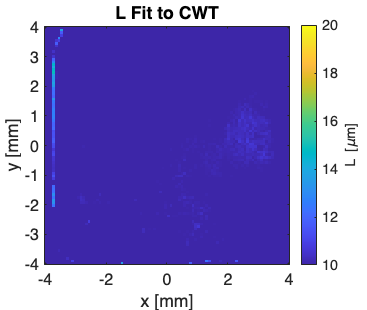

% Plot the 2D Bragg Metrology output data
test_n1  = BM2D.n1_fits.*10^3;
test_L   = BM2D.L_fits.*10^6;
test_GoF = BM2D.gof_fits;

x_span = linspace(-4,4,size(test_n1,1));
y_span = linspace(-4,4,size(test_n1,2));

test_n1(test_n1 >= 10) = nan;
test_n1(test_n1 <= 1) = nan;

test_L(test_L >= 20) = nan;
test_L(test_L <= 10) = nan;

% test_GoF(test_GoF >= 20) = nan;
test_GoF(test_GoF <= 0.60) = nan;

figure; % n1
imagesc(x_span,y_span,test_n1); title('n_{1} Fit to CWT'); colorbar;
% colormap('hot')
set(gca,'FontSize',16,'YDir','normal','CLim',[1 14]);
c = colorbar;
c.Label.String = 'n_1 \times 10^{-3}';
xlabel('x [mm]'); ylabel('y [mm]');
% Regular % [x y w h]
set(gcf, 'Units', 'Inches', 'Position', [5, 5, 5.1, 4.3])

figure; % L
imagesc(x_span,y_span,test_L); title('L Fit to CWT'); colorbar;
% colormap('hot')
set(gca,'FontSize',16,'YDir','normal','CLim',[10 20]);
c = colorbar;
c.Label.String = 'L [\mum]';
xlabel('x [mm]'); ylabel('y [mm]');
set(gcf, 'Units', 'Inches', 'Position', [5, 5, 5.1, 4.3])

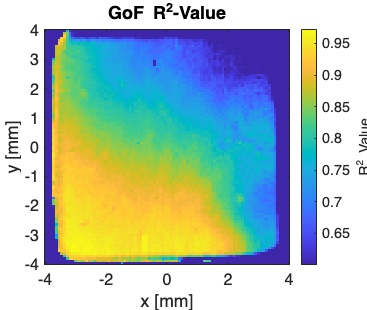


figure; % R-squared
imagesc(x_span,y_span,test_GoF); title('GoF R^{2}-Value'); colorbar;
% colormap('hot')
set(gca,'FontSize',16,'YDir','normal');
c = colorbar;
c.Label.String = 'R^2 Value';
xlabel('x [mm]'); ylabel('y [mm]');
set(gcf, 'Units', 'Inches', 'Position', [5, 5, 5.1, 4.3])

% Play video of processed data
figure;
playVideo(vidObj, Process_Frames)


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%% FUNCTIONS %%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Read in specified frames and convert to grayscale array
function ProcessFrames = readAndConvertVideo(vidObj, framesToRead)
% Pre-allocate based on how many frames we'll read
% Note: We can pre-allocate the final 3D array once we know how many frames:
nFrames = length(framesToRead);

% (Optional) Check if video is grayscale or color:
% For demonstration, let's assume it's color:
% ProcessFrames = zeros(vidObj.Height, vidObj.Width, 3, nFrames, 'uint8');

% Pre-allocate a 3D grayscale array:
ProcessFrames = zeros(vidObj.Height, vidObj.Width, nFrames, 'uint8');

% Read and convert the frames in a loop
for idx = 1 : nFrames
    f = framesToRead(idx); % frame to read
    % Read the frame
    frameRGB = read(vidObj, f);
    % Convert to grayscale and store
    ProcessFrames(:, :, idx) = im2gray(frameRGB);
end

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Function to play the processed frames video
function [] = playVideo(vidObj, ProcessFrames)
% Play the video of skipped frames
for idx = 1 : size(ProcessFrames, 3)
    imshow(ProcessFrames(:, :, idx), Colormap=parula); % imshow and change colors

    drawnow;
    pause(1 / vidObj.FrameRate)  % you can enable this if you want real-time playback
end
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Function to crop video to square
function ProcessFrames = cropVideo(vidObj, ProcessFrames, sz, xNudge, yNudge)
verticalCrop   = vidObj.Height/2 - sz/2 : vidObj.Height/2 + sz/2 -1;
horizontalCrop = vidObj.Width/2  - sz/2 : vidObj.Width/2  + sz/2 -1;
ProcessFrames = ProcessFrames(verticalCrop + yNudge, horizontalCrop + xNudge, :);
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Function to integrate image data to a full power meter readout
function PowerMeter = powerMeterReadout(framesToRead, Process_Frames)
PowerMeter = zeros(1,length(framesToRead)); % Pre-allocate PM Readout

for idx = 1:length(framesToRead)
    PowerMeter(idx) = sum(sum(Process_Frames(:,:,idx)));
end

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Function to region average the subarrays at every frame
function avgBlock = regionSums(imageBlock)
% 'imageBlock' is a 1x1xnumFrames cell where the 1x1s are subregions
numFrames = size(imageBlock,3);
for frameNum = 1:numFrames
    cellArray = imageBlock{1,1,frameNum};

    % Assume 'cellArray' is a numRowsxnumCols cell array where each cell contains a numeric matrix
    [numRows, numCols] = size(cellArray);

    % Initialize a matrix to store the region averages for one frame
    avgMatrix = zeros(numRows, numCols);
    % avgBlock  = zeros(numRows, numCols, numFrames);

    % Loop through each cell and compute the region average
    for r = 1:numRows
        for c = 1:numCols
            % Compute the mean of the numeric values inside the cell
            avgMatrix(r, c) = mean(cellArray{r, c}(:));
        end
    end

    avgBlock(:,:,frameNum) = avgMatrix;

end
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Function to section images into subarrays
function imageCells = subDivideImage(Process_Frames, frameNum, blockSize)
frame = Process_Frames(:,:,frameNum);
% imagesc(frame)

% Read the input image
img = frame;  % Replace with your image file
[height, width, channels] = size(img);

% Define the block size (50x50 pixels)
% blockSize = 6;

% Compute number of complete blocks in rows and columns
numRows = floor(height / blockSize);
numCols = floor(width / blockSize);

% Trim the image to make it evenly divisible (if necessary)
trimmedImg = img(1:numRows*blockSize, 1:numCols*blockSize, :);

% Define row and column size vectors for mat2cell
rowSizes = repmat(blockSize, 1, numRows);  % [50, 50, ..., 50]
colSizes = repmat(blockSize, 1, numCols);  % [50, 50, ..., 50]

% Split the image into a cell array using mat2cell
imageCells = mat2cell(trimmedImg, rowSizes, colSizes, channels);

% % Display an example block (e.g., top-left block)
% imshow(imageCells{44,22}); title('Example Block');
end